# Detailed analysis of the 1DOF cell model

clear all; close all; clc;
addpath("Functions and Scripts\");
addpath("1DOF\");
set_env;
load("cell_1dof_pstrain.mat")
load("cell_1dof_pstress.mat")
load("cell_1dof_nostrain.mat")
load("res_1dof_pstrain.mat")
%

% Data --------------------------------------------------------------
% Constants
eps1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive

% Physical quantities
syms V

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x) epsilon1_max

## Equations

% Geometry ------------------------------

dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f; 

pstrain = sstrain1(pstrain_1dof, "PSTRAIN")

pstrain = struct with fields:
         w: w_0
       t_p: tp_0*((nu*(((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2) - 1))/(nu - 1) + 1)
         l: l_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2)
         A: l_0*w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2)
        dA: w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2)
       dCp: (epsilon_p*w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2))/(tp_0*((nu*(((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2) - 1))/(nu - 1) + 1))
       dCf: (epsilon_f*w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2))/(tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)
        dC: 1/((tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)/(epsilon_f*w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2)) + (2*tp_0*((nu*(((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2) - 1))/(nu - 1) + 1))/(epsilon_p*w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2)))
         C: [1×1 symfun]
    Cplane: [1×1 symfun]
     x_min: tf_0
     x_max: ((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2) - 1 == epsilon1_max
       Vol: l_0*tp_0*w_0*((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2)*((nu*(((tf_0 - x)^2/(4*l_0^2) + 1)^(1/2) - 1))/(nu - 

pstress = sstrain1(pstress_1dof, "PSTRESS");
nostrain = nostrain_1dof;

% Range limit
x_min = vpa(sdata1(pstrain.x_min), 4)

$$x\_min = 0.0001$$

x_max = subs(sstrain1(pstrain.x_max), epsilon1_max, eps1_max);
x_max = vpa(sdata1(rhs(isolate(x_max, x))), 4)

$$x\_max = 0.01611$$

x_minmax = [double(x_min) double(x_max)];

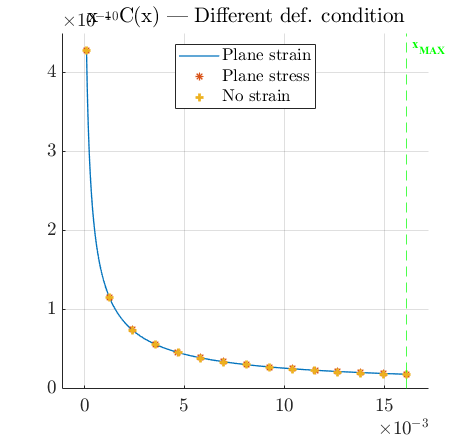

% C(x): Plane strain - Plane stress - No strain
myfig(1,"x - C(x)"); clf; hold on
fplot(x, sdata1(pstrain.C), x_minmax, '-', 'LineWidth', 1, 'DisplayName', 'Plane strain')
fplot(x, sdata1(pstress.C), x_minmax, '*', 'LineWidth', 1, 'DisplayName', 'Plane stress')
fplot(x, sdata1(nostrain.C), x_minmax, '+', 'LineWidth',2, 'DisplayName', 'No strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) | Different def. condition")
xlim("padded")

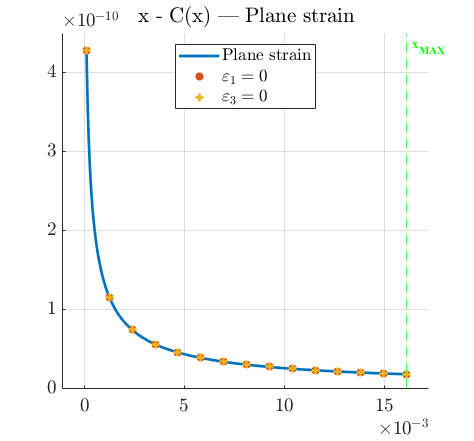

% C(x): Plane strain with epsilon_1 = 0 or epsilon_3 = 0
myfig(2,"x - C(x)"); clf; hold on
fplot(x, sdata1(pstrain.C), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane strain')
fplot(x, sdata1(subs(pstrain.C, epsilon_1, 0)), x_minmax, '*', 'LineWidth',2, 'DisplayName', '$\varepsilon_1 = 0$')
fplot(x, sdata1(subs(pstrain.C, epsilon_3, 0)), x_minmax, '+', 'LineWidth',2, 'DisplayName', '$\varepsilon_3 = 0$')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) | Plane strain")
xlim("padded")

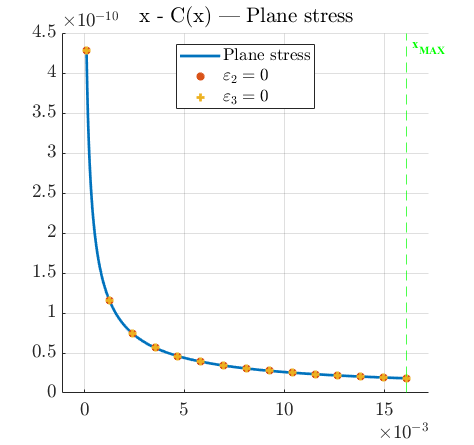

% C(x): Plane strain with epsilon_1 = 0 or epsilon_2 = 0
myfig(3,"x - C(x)"); clf; hold on
fplot(x, sdata1(pstress.C), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, sdata1(subs(pstress.C, epsilon_2, 0)), x_minmax, '*', 'LineWidth',2, 'DisplayName', '$\varepsilon_2 = 0$')
fplot(x, sdata1(subs(pstress.C, epsilon_3, 0)), x_minmax, '+', 'LineWidth',2, 'DisplayName', '$\varepsilon_3 = 0$')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) | Plane stress")
xlim("padded")

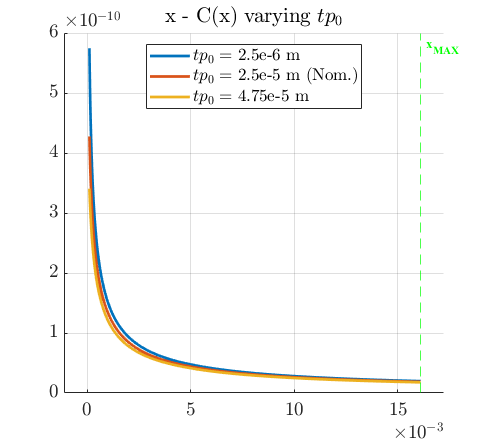

% C(x): Plane strain with different tp_0
tp0_range = sdata1(tp_0) - 0.9*sdata1(tp_0) : 0.9*sdata1(tp_0) : sdata1(tp_0) + 0.9*sdata1(tp_0);
C_tp0 = subs(sdata1(pstrain.C, 'except', tp_0), tp_0, tp0_range);

myfig(4, "x - C(x) varying $tp_0$"); hold on
for i = 1:length(tp0_range)
    if i == 2
        name = strjoin(["$tp_0 =$", string(vpa(tp0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$tp_0 =$", string(vpa(tp0_range(i),4)), "m"]);
    end
    
    fplot(x, pickelem(C_tp0(x), i), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) varying $tp_0$")
xlim("padded")

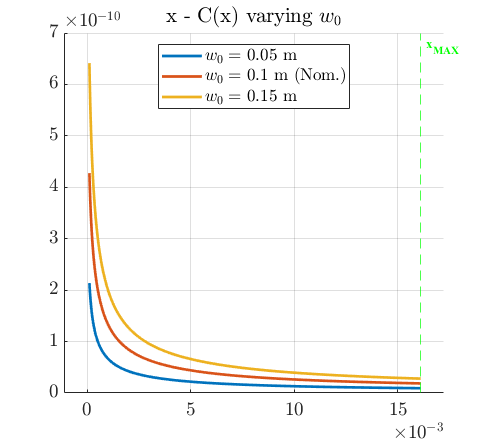

% C(x): Plane strain with different w_0
w0_range = sdata1(w_0) - 0.5*sdata1(w_0) : 0.5*sdata1(w_0) : sdata1(w_0) + 0.5*sdata1(w_0);
C_w0 = subs(sdata1(pstrain.C, 'except', w_0), w_0, w0_range);

myfig(5, "x - C(x) varying $w_0$"); hold on
for i = 1:length(w0_range)
    if i == 2
        name = strjoin(["$w_0 =$", string(vpa(w0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$w_0 =$", string(vpa(w0_range(i),4)), "m"]);
    end
    fplot(x, pickelem(C_w0(x), i), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) varying $w_0$")
xlim("padded")

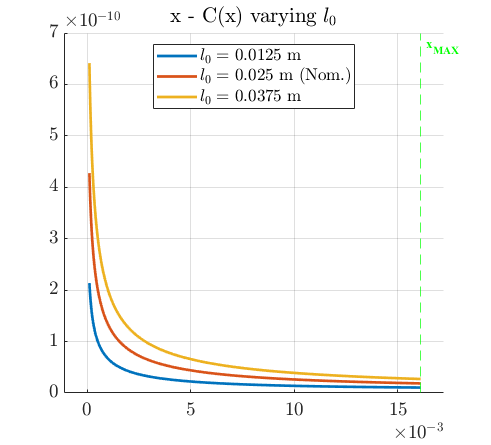

% C(x): Plane strain with different l_0
l0_range = sdata1(l_0) - 0.5*sdata1(l_0) : 0.5*sdata1(l_0) : sdata1(l_0) + 0.5*sdata1(l_0);
C_l0 = subs(sdata1(pstrain.C, 'except', l_0), l_0, l0_range);

myfig(6, "x - C(x) varying $l_0$"); hold on
for i = 1:length(l0_range)
    if i == 2
        name = strjoin(["$l_0 =$", string(vpa(l0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$l_0 =$", string(vpa(l0_range(i),4)), "m"]);
    end
    fplot(x, pickelem(C_l0(x), i), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) varying $l_0$")
xlim("padded")

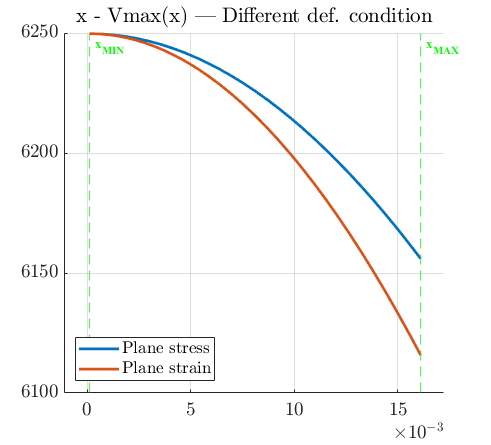

% Vmax(x): Plane stress - Plane strain
myfig(7,"x - Vmax(x)"); clf; hold on
fplot(x, sdata1(pstress.Vmax), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, sdata1(pstrain.Vmax), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane strain')
myxline(double(x_min), "x_{MIN}");
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','southwest')
title("x - Vmax(x) | Different def. condition")
xlim("padded")


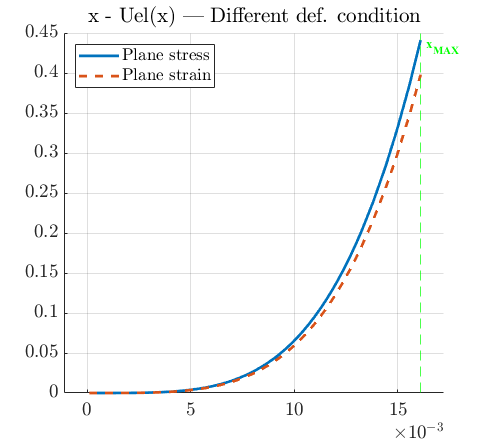

% Uel(x): Plane stress - Plane strain
myfig(8,"x - Uel(x)"); clf; hold on;
fplot(x, sdata1(pstress.Uel), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, sdata1(pstrain.Uel), x_minmax, '--', 'LineWidth',2, 'DisplayName', 'Plane strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','northwest')
title("x - Uel(x) | Different def. condition")
xlim("padded")


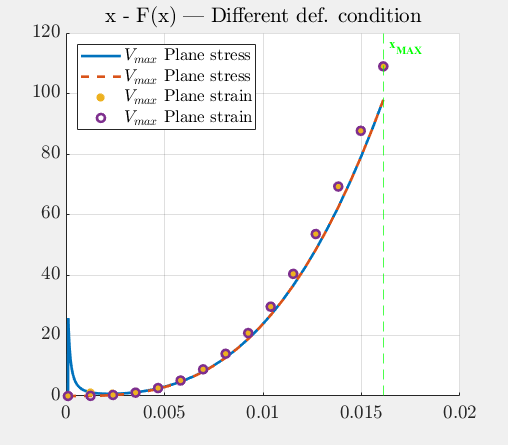

% F(x): Plane stress - Plane strain
myfig(9,"x - F(x)"); clf; hold on;
fplot(x, sdata1(pstress.FVmax), x_minmax, 'LineWidth', 2, 'DisplayName', '$V_{max}$ Plane stress')
fplot(x, sdata1(pstress.FVmin), x_minmax, '--', 'LineWidth', 2, 'DisplayName', '$V_{max}$ Plane stress')
fplot(x, sdata1(pstrain.FVmax), x_minmax, '*', 'LineWidth', 2, 'DisplayName', '$V_{max}$ Plane strain')
fplot(x, sdata1(pstrain.FVmin), x_minmax, 'o', 'LineWidth', 2, 'DisplayName', '$V_{max}$ Plane strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','northwest') 
title("x - F(x) | Different def. condition")

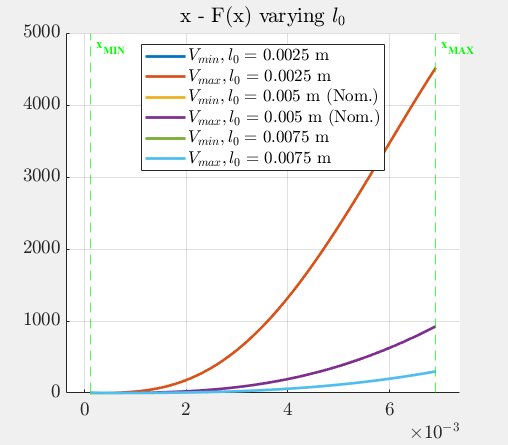

% F(x): Plane strain with different l_0
l0_range = sdata1(l_0) - 0.9*sdata1(l_0) : 0.1*sdata1(l_0) : sdata1(l_0) + 2*sdata1(l_0);
x_range = res_1dof_pstrain.x_startend;
FVmin_l0 = cell(length(l0_range), 1);
FVmax_l0 = cell(length(l0_range), 1);

FVmin_l0tmp = subs(sdata1(pstrain.FVmin, 'except', l_0), x, x_range);
FVmax_l0tmp = subs(sdata1(pstrain.FVmax, 'except', l_0), x, x_range);
for i = 1:length(l0_range)
    FVmin_l0{i} = double(subs(FVmin_l0tmp, l_0, l0_range(i)));
    FVmax_l0{i} = double(subs(FVmax_l0tmp, l_0, l0_range(i)));
end
FVmin_l0;

myfig(10, "x - F(x) varying $l_0$"); hold on
for i = 1:3
    if i == 2
        nameVmin = strjoin(["$V_{min}, l_0 =$", string(vpa(l0_range(i),4)), "m (Nom.)"]);
        nameVmax = strjoin(["$V_{max}, l_0 =$", string(vpa(l0_range(i),4)), "m (Nom.)"]);
    else
        nameVmin = strjoin(["$V_{min}, l_0 =$", string(vpa(l0_range(i),4)), "m"]);
        nameVmax = strjoin(["$V_{max}, l_0 =$", string(vpa(l0_range(i),4)), "m"]);
    end
    plot(x_range, FVmin_l0{i}, 'LineWidth', 2, 'DisplayName', nameVmin)
    plot(x_range, FVmax_l0{i}, 'LineWidth', 2, 'DisplayName', nameVmax)
end
myxline(double(x_range(1)), "x_{MIN}");
myxline(double(x_range(end)), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - F(x) varying $l_0$")
xlim("padded")

% Energy and energy density
Uel_l0 = zeros(length(l0_range),1);
uel_l0 = zeros(length(l0_range),1);

for i = 1:length(l0_range)
    Uel_l0(i) = trapz(x_range, FVmax_l0{i}) - trapz(x_range, FVmin_l0{i});
    uel_l0(i) = Uel_l0(i) / sdata1((w_0 * (2 *l_0 * tp_0 + (x_range(end) - tf_0) / 2 * sqrt(l_0^2 - x_range(end)^2 / 4))));
end


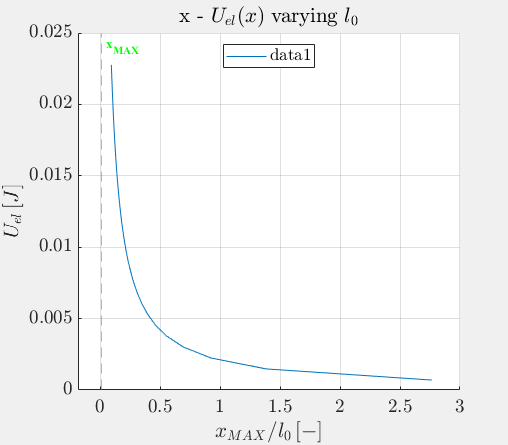

%
myfig(11, "x_max / l_0 - Uel(x) varying $l_0$"); hold on
plot(x_range(end) ./ l0_range, Uel_l0)
myxline(double(x_range(end)), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - $U_{el}(x)$ varying $l_0$")
xlabel("$x_{MAX} / l_0 \, [-]$")
ylabel("$U_{el} \, [J]$")
xlim("padded")

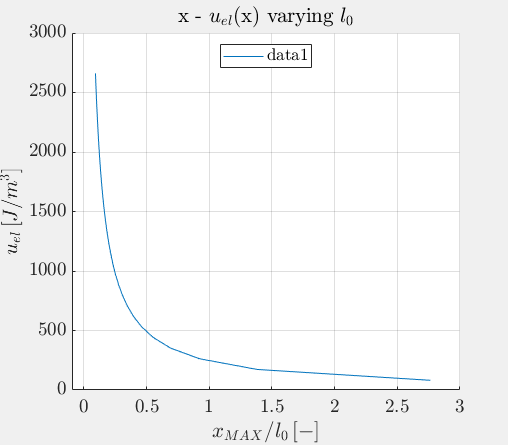


myfig(12, "x_max / l_0 - uel(x) varying $l_0$"); hold on
plot(x_range(end) ./ l0_range, uel_l0)
legend('FontWeight','bold', 'Location','north')
title("x - $u_{el}$(x) varying $l_0$")
xlabel("$x_{MAX} / l_0 \, [-]$")
ylabel("$u_{el} \, [J/m^3]$")
xlim("padded")

% sdata1(res_1dof_pstrain.C)
cmax = res_1dof_pstrain.Cmax
cmin = res_1dof_pstrain.Cmin
max(res_1dof_pstrain.Vmax_vec)^2 / 2 * (cmax - cmin)
max(res_1dof_pstrain.Vmax_vec)^2 / 2 * (cmax)
